clc
clear
close all

bag1 = rosbag('/LAB3/LocationD.bag');
bagselect = select(bag1, 'Topic', '/vectornav');
msgStructs = readMessages(bagselect, 'DataFormat', 'struct');

L = length(msgStructs);

accels = zeros(L,3);
gyros = zeros(L,3);
t = zeros(L,1);
line = "asdf";
times = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs);
timens = cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs);

for i = 1:L 
    line = string(msgStructs{i}.Data);
    data1 = split(line, "*");
    data2 = split(data1(1), ",");

    if length(data2) ~= 13
        continue
    else
        accels(i,:) = double(data2(8:10));
        gyros(i,:) = double(data2(11:13));
        t(i) = times(i) + timens(i)*10^-9;
    end
end

j = 1;
for i = 1:L
    if t(i) == 0
        indeces(j) = i;
        j = j + 1;
    end
end

j = 0;
for i = 1:length(indeces)
    index1 = indeces(i) - j;
    t(index1) = [];
    gyros(index1,:) = [];
    accels(index1,:) = [];
    j = j + 1;
end

% t = abs(t);
% t = t - t(1);
t = t - t(1);

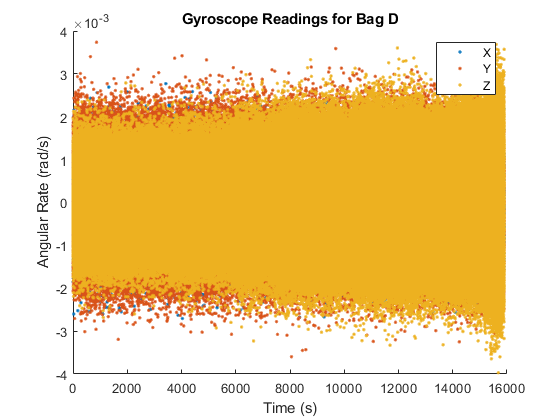

figure
hold on; scatter(t, [gyros(:,1), gyros(:,2), gyros(:,3)], '.', 'linewidth', .1); title('Gyroscope Readings for Bag D'); 
xlabel('Time (s)'); ylabel('Angular Rate (rad/s)'); legend('X', 'Y', 'Z'); set(gcf,'Visible','on'); hold off;

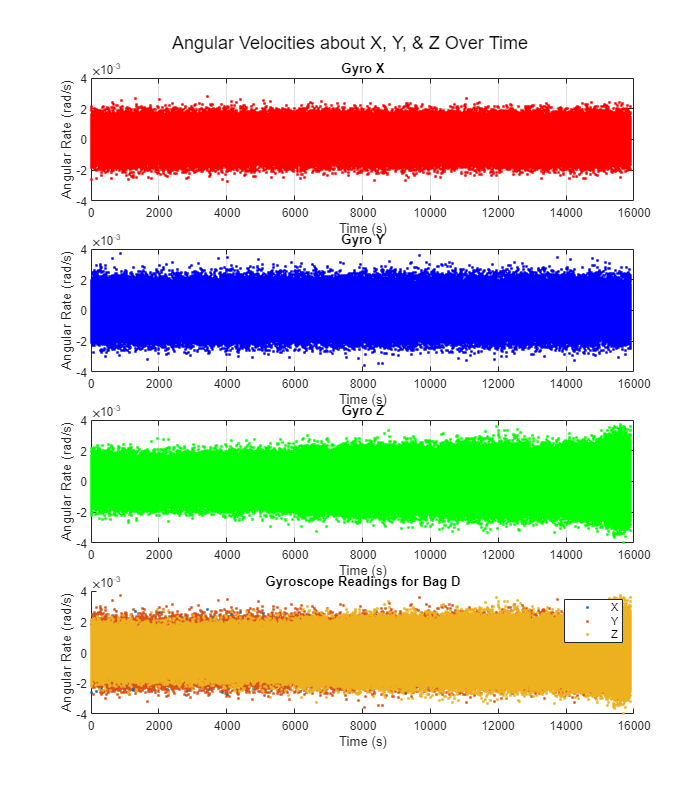

figure
set(gcf, 'position', [0, 0, 2100, 2400])
hold on
subplot(4,1,1); plot(t, gyros(:,1), 'r.', 'linewidth', .1); title('Gyro X'); xlabel('Time (s)'); ylabel('Angular Rate (rad/s)'); grid on;
subplot(4,1,2); plot(t, gyros(:,2), 'b.', 'linewidth', .1); title('Gyro Y'); xlabel('Time (s)'); ylabel('Angular Rate (rad/s)'); grid on;
subplot(4,1,3); plot(t, gyros(:,3), 'g.', 'linewidth', .1); title('Gyro Z'); xlabel('Time (s)'); ylabel('Angular Rate (rad/s)'); grid on;
subplot(4,1,4); scatter(t, [gyros(:,1), gyros(:,2), gyros(:,3)], '.', 'linewidth', .1); title('Gyroscope Readings for Bag D'); xlabel('Time (s)'); ylabel('Angular Rate (rad/s)'); legend('X', 'Y', 'Z');
sgtitle('Angular Velocities about X, Y, & Z Over Time'); hold off;

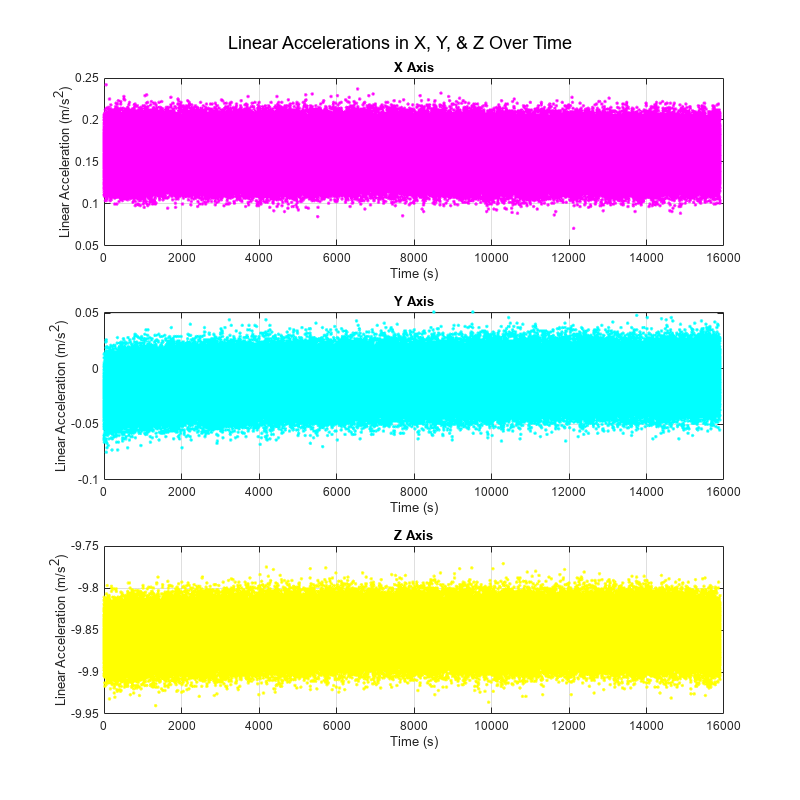

figure
set(gcf, 'position', [0, 0, 2400, 2400])
hold on
subplot(3,1,1); plot(t, accels(:,1), 'm.', 'linewidth', .1); title('X Axis'); xlabel('Time (s)'); ylabel('Linear Acceleration (m/s^2)'); grid on;
subplot(3,1,2); plot(t, accels(:,2), 'c.', 'linewidth', .1); title('Y Axis'); xlabel('Time (s)'); ylabel('Linear Acceleration (m/s^2)'); grid on;
subplot(3,1,3); plot(t, accels(:,3), 'y.', 'linewidth', .1); title('Z Axis'); xlabel('Time (s)'); ylabel('Linear Acceleration (m/s^2)'); grid on;
sgtitle('Linear Accelerations in X, Y, & Z Over Time'); hold off;

t0 = 1/40;
L = length(t);

maxNumM = 100;
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM);
m = ceil(m);
m = unique(m);

avars = zeros(numel(m), 6);
adevs = zeros(numel(m),6);
taus = zeros(numel(m),6);

N = zeros(6,1);  % angle/velocity random walk
K = zeros(6,1);  % rate/accel. random walk
B = zeros(6,1);  % bias instability
lineNs = zeros(numel(m),6);
lineKs = zeros(numel(m),6);
lineBs = zeros(numel(m),6);
tauBs = zeros(6,1);

items = [gyros(:,1), gyros(:,2), gyros(:,3), accels(:,1), accels(:,2), accels(:,3)];

% tau = m*10;

% for i = 1:6
%     integrated_value = cumsum(params(i), 1)*t0;
%     if i > 3
%         integrated_value = cumsum(integrated_value,1)*t0;
%     end
%     for j = 1:numel(m)
%         mi = m(i);
%         avars(j,i) = sum((integrated_value(1+2*mi:L) - 2*integrated_value(1+mi:L-mi) + integrated_value(1:L-2*mi)).^2, 1);
%     end
%     avars(:,i) = avars(:,i) ./ (2*tau.^2 .* (L - 2*m));
%     adevs(:,i) = sqrt(avars(:,i));
% end

slopes = [-.5; .5; 0];

for i = 1:6
    for j = 1:3
        slope = slopes(j);
    
        [avars(:,i), taus(:,i)] = allanvar(items(:,i), m, t0);
        adevs(:,i) = sqrt(avars(:,i));
    
        logtau = log10(taus(:,i));
        logadev = log10(adevs(:,i));
        dlogadev = diff(logadev) ./ diff(logtau);
        [~, k] = min(abs(dlogadev - slope));
    
        b = logadev(k) - slope*logtau(k);
        
        if j == 1
            logN = slope*log10(1) + b;
            N(i,:) = 10^logN;
            lineNs(:,i) = N(i,:) ./ sqrt(taus(:,i));
        elseif j == 2
            logK = slope*log10(3) + b;
            K(i,:) = 10^logK;
            lineKs(:,i) = K(i,:) .* sqrt(taus(:,i)/3);
        elseif j == 3
            tauBs(i,:) = taus(k,i);
            scfB = sqrt(2*log10(2)/pi);
            logB = b - log10(scfB);
            B(i,:) = 10^logB;
            lineBs(:,i) = B(i,:) * scfB * ones(size(taus(:,i)));
        end
    end
end

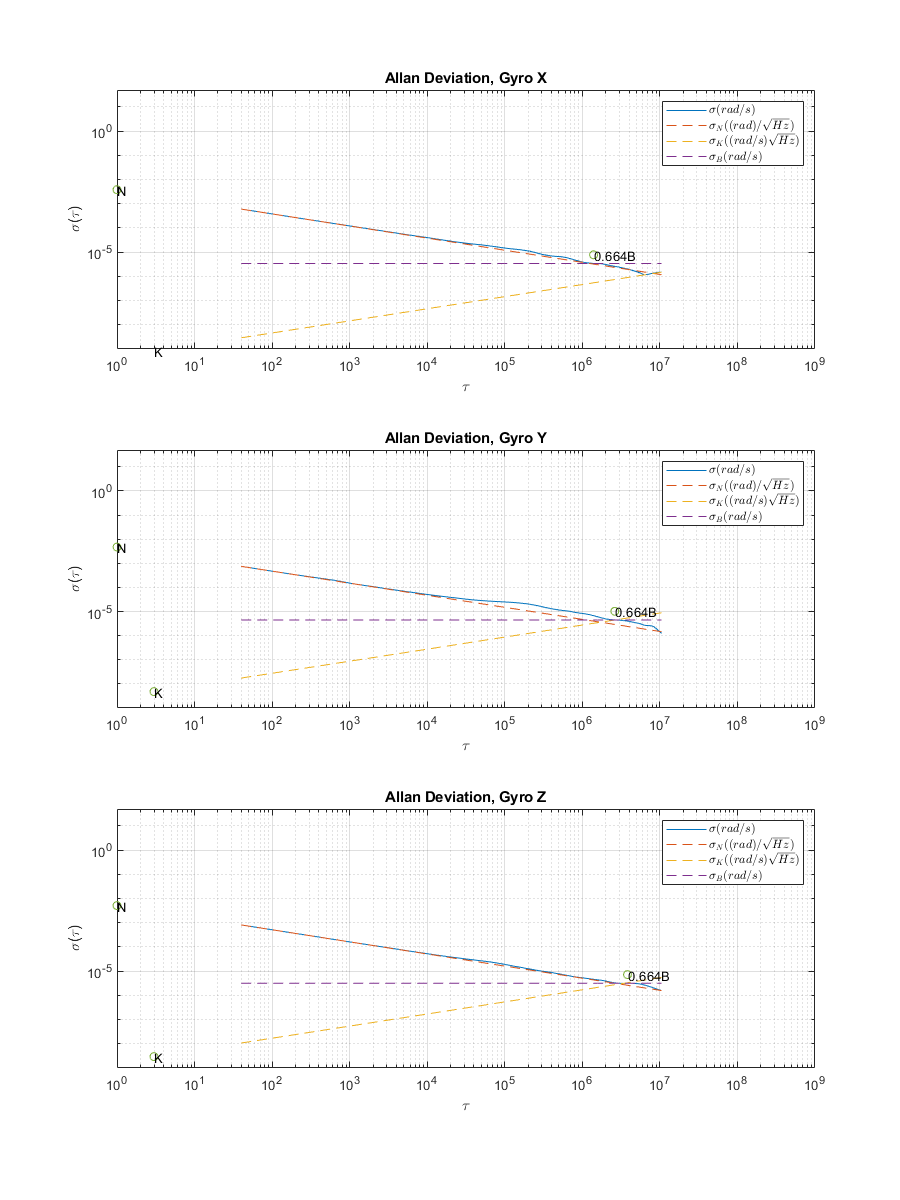

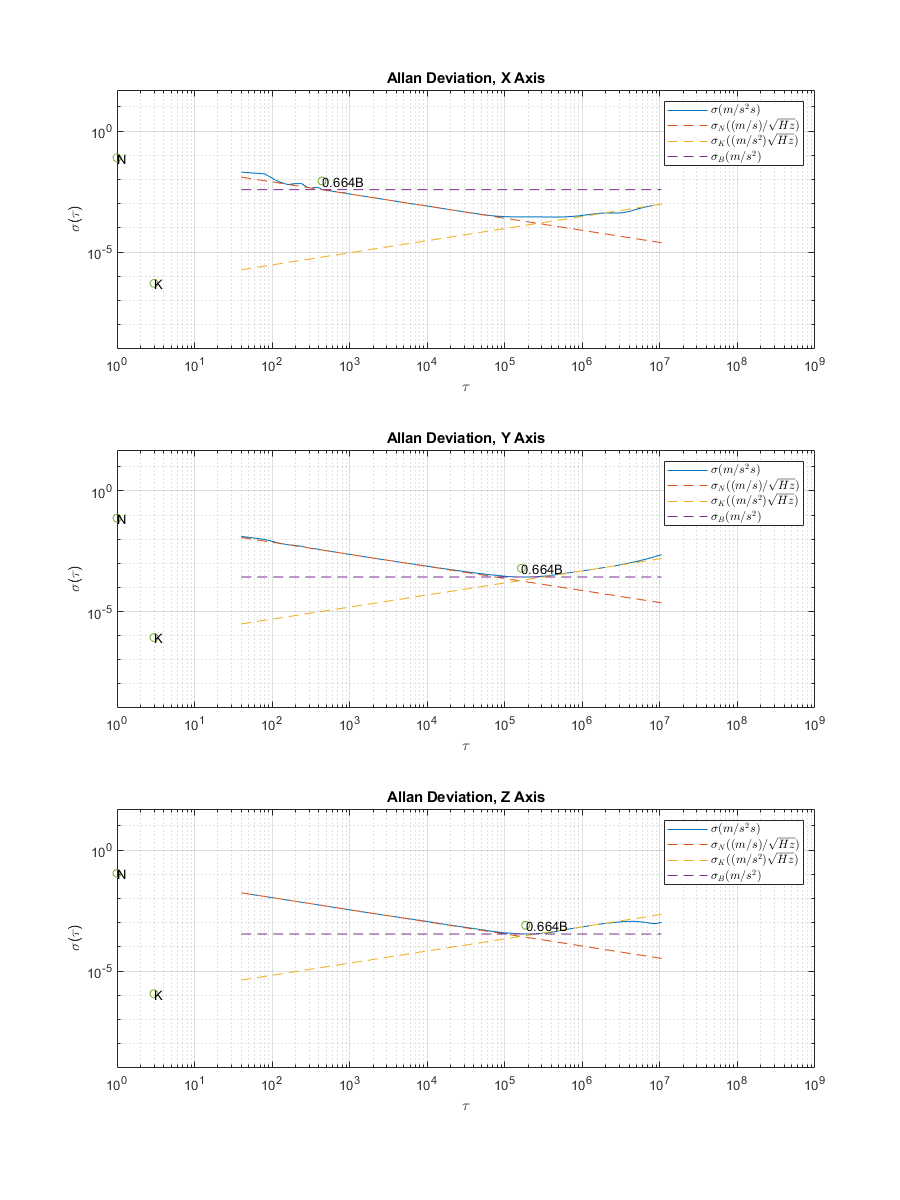

tauParams = [ones(6,1), 3*ones(6,1), tauBs];
params = [N, K, B];

titles = ["Gyro X" "X Axis"; "Gyro Y" "Y Axis"; "Gyro Z" "Z Axis"];
legends = ["$\sigma (rad/s)$" "$\sigma_N ((rad)/\sqrt{Hz})$" "$\sigma_K ((rad/s)\sqrt{Hz})$" "$\sigma_B (rad/s)$";
           "$\sigma (m/s^2s)$" "$\sigma_N ((m/s)/\sqrt{Hz})$" "$\sigma_K ((m/s^2)\sqrt{Hz})$" "$\sigma_B (m/s^2)$"];

for i = 1:2
    figure
    set(gcf, 'position', [0, 0, 900, 1200]); hold on; set(gcf,'Visible','on');
    for j = 1:3
        ij = j + 3*(i - 1);
        subplot(3,1,j); loglog(taus(:,ij), adevs(:,ij), taus(:,ij), [lineNs(:,ij), lineKs(:,ij), lineBs(:,ij)], '--', tauParams(ij,:), params(ij,:), 'o'); 
        title("Allan Deviation, " + titles(j,i)); xlabel('\tau'); ylabel('\sigma(\tau)'); legend(legends(i,1), legends(i,2), legends(i,3), legends(i,4), 'Interpreter', 'latex'); 
        text(tauParams(ij,:), params(ij,:), {'N', 'K', '0.664B'}); grid on;  
        set(gca, 'XLim', [-inf 10e8], 'YLim', [10e-10, 50]);
%         axis equal; 
    end
    linkaxes; hold off;
end